# Wavelet Scalogram Feature Generator

This script is intended to service as an example of how to load, process, and generate wavelet scalogram features from an audio file.

## List files

Find all data files in the '\EnvNoiseDetector\data\DataExamplesv2' directory. 

% Find base directory
basedir = fileparts(pwd);

% Feature storage directory and file name
featuredir = fullfile(basedir,"data","Features");
featurefilename = "FeaturesSNR6WaveletFeaturesv1";

% Find data examples directory
datadir = fullfile(basedir,"data","DataExamplesv2");

% File descriptions
fileDescripts = readtable(fullfile(datadir,"FileDescriptions.xlsx"),'TextType','string');
fileDescripts.AircraftPresent = fileDescripts.AircraftPresent == "Y";
fileDescripts.Contaminated = fileDescripts.Contaminated == "Y";

contaminationFiles = fileDescripts.FileName(fileDescripts.Contaminated);
signalFiles = fileDescripts.FileName(~fileDescripts.Contaminated);

% Create image output directories
signalImagesDir = fullfile(featuredir, "Images", "Signal");
contaminationImagesDir = fullfile(featuredir, "Images", "Contamination");
if ~exist(signalImagesDir, "dir")
    mkdir(signalImagesDir);
end
if ~exist(contaminationImagesDir, "dir")
    mkdir(contaminationImagesDir);
end

% Create pool of MATLAB workers
% tic; parpool('local',4); toc

## Processing parameters

List and define processing parameters.

% processing type
type = "WaveletScalogram";

% record or block duration (s)
tblock = 5;

% fractional overlap between blocks, 0 <= foverlap <= 1
foverlap = 0.25;

% frequency limits for octave
freqlim = [30 20000];

% Signal to noise ratio
snrdB = 6;

## Signal files

Process clean signal files and store features. 

This takes about 40 minutes on a Core i7-7700k quad-core processor with 16 GB ram and 4 MATLAB parallel workers for 1s clips.

This takes about 30 minutes on a Core i7-7700k quad-core processor with 16 GB ram and 4 MATLAB parallel workers for 3s clips.

This takes about 40 minutes on a Core i7-7700k quad-core processor with 16 GB ram and 4 MATLAB parallel workers for 5s clips.

% Loop over all signal files
tic
parfor ifile = 1:length(signalFiles)
    % Load file
    [x,fs] = audioread(fullfile(datadir,signalFiles(ifile)));
    
    % Convert processing parameters to samples
    nblock = tblock*fs;
    noverlap = round(foverlap*nblock);
    
    xblock = spectralReshape(x,noverlap,nblock);
    
    % Process each block into a scalogram
    fileName = signalFiles(ifile).split(".");
    fileName = fileName(1);
    WaveletScalogramFeatures(xblock,224,224,fileName,signalImagesDir);
end

toc

Elapsed time is 2442.247053 seconds.


## Contamination

Now add contamination to the clean signals and generate features. Each clean signal will have a contamination signal randomly assigned to it and the contamination signal will be replicated to make the length of the clean signal. Then the two signals will be super imposed and processed to generate the features. 

This takes about 40 minutes on a Core i7-7700k quad-core processor with 16 GB ram and 4 MATLAB parallel workers for 1s clips.

This takes about 30 minutes on a Core i7-7700k quad-core processor with 16 GB ram and 4 MATLAB parallel workers for 3s clips.

This takes about 40 minutes on a Core i7-7700k quad-core processor with 16 GB ram and 4 MATLAB parallel workers for 5s clips.

% Make contamination signal assignments
% one contamination file index for each of the signal files
rng(42);
contaminationAssign = randi(length(contaminationFiles),1,length(signalFiles));

% Process signal files one at a time and add contamination signals
tic
xfeaturecell = cell(length(signalFiles),1);
parfor ifile = 1:length(signalFiles)
    contaminationFilesLocal = contaminationFiles;
    % Load files
    [x,fs] = audioread(fullfile(datadir,signalFiles(ifile)));
    [n,fn] = audioread(fullfile(datadir,contaminationFilesLocal(contaminationAssign(ifile))));
    assert(fs == fn,'featureGenerator:UnequalSampleRates',...
        'Sample rates for the signal data and the contamination data are not equal.')
    
    % Adjust contamination signal length
    n = repmat(n,ceil(length(x)/length(n)),1);
    n = n(1:length(x));
    
    % Convert processing parameters to samples
    nblock = tblock*fs;
    noverlap = round(foverlap*nblock);
    
    % Reshape into blocks
    xblock = spectralReshape(x,noverlap,nblock);
    n = spectralReshape(n,noverlap,nblock);
    
    % Super impose signal and noise together
    xblock = addNoise(xblock,n,snrdB);
    
    % Process each block into a scalogram
    fileName = signalFiles(ifile).split(".");
    fileName = fileName(1);
    contaminationFileName = contaminationFilesLocal(contaminationAssign(ifile)).split(".");
    contaminationFileName = contaminationFileName(1);
    WaveletScalogramFeatures(xblock,224,224,strcat(fileName,"_",contaminationFileName),contaminationImagesDir);
end
toc

Elapsed time is 2674.022327 seconds.


## Save output

Save the computed features to a zip archive.

% Save to file
zip(fullfile(featuredir,"WaveletScalograms_5s.zip"),fullfile(featuredir,"Images"));

## GoogleNet Model

Use transfer learning with a pre-trained neural net to classify images. This takes about 3 minutes for 5s clips, 6 minutes for 3s clips and an hour for 1s clips on a GeForce GTX 1080.

allImages = imageDatastore(fullfile(featuredir,"Images"),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

% Split the images into Training, Validation and Test sets
rng(63)
[imgsTrain,imgsValidationTest] = splitEachLabel(allImages,0.5,'randomized');
[imgsValidation,imgsTest] = splitEachLabel(imgsValidationTest,0.5,'randomized');

% Instantiate the model and replace layers to fit learning a binary classifier
net = googlenet;
lgraph = layerGraph(net);
lgraph = removeLayers(lgraph,{'pool5-drop_7x7_s1','loss3-classifier','prob','output'});

numClasses = numel(categories(imgsTrain.Labels));
newLayers = [
    dropoutLayer(0.6,'Name','newDropout')
    fullyConnectedLayer(numClasses,'Name','fc','WeightLearnRateFactor',5,'BiasLearnRateFactor',5)
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classoutput')];
lgraph = addLayers(lgraph,newLayers);

lgraph = connectLayers(lgraph,'pool5-7x7_s1','newDropout');
inputSize = net.Layers(1).InputSize;

% Specify training options
options = trainingOptions('sgdm',...
    'MiniBatchSize',15,...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-4,...
    'ValidationData',imgsValidation,...
    'ValidationFrequency',10,...
    'ValidationPatience',Inf,...
    'Verbose',0,...
    'ExecutionEnvironment','gpu',...
    'Plots','training-progress');

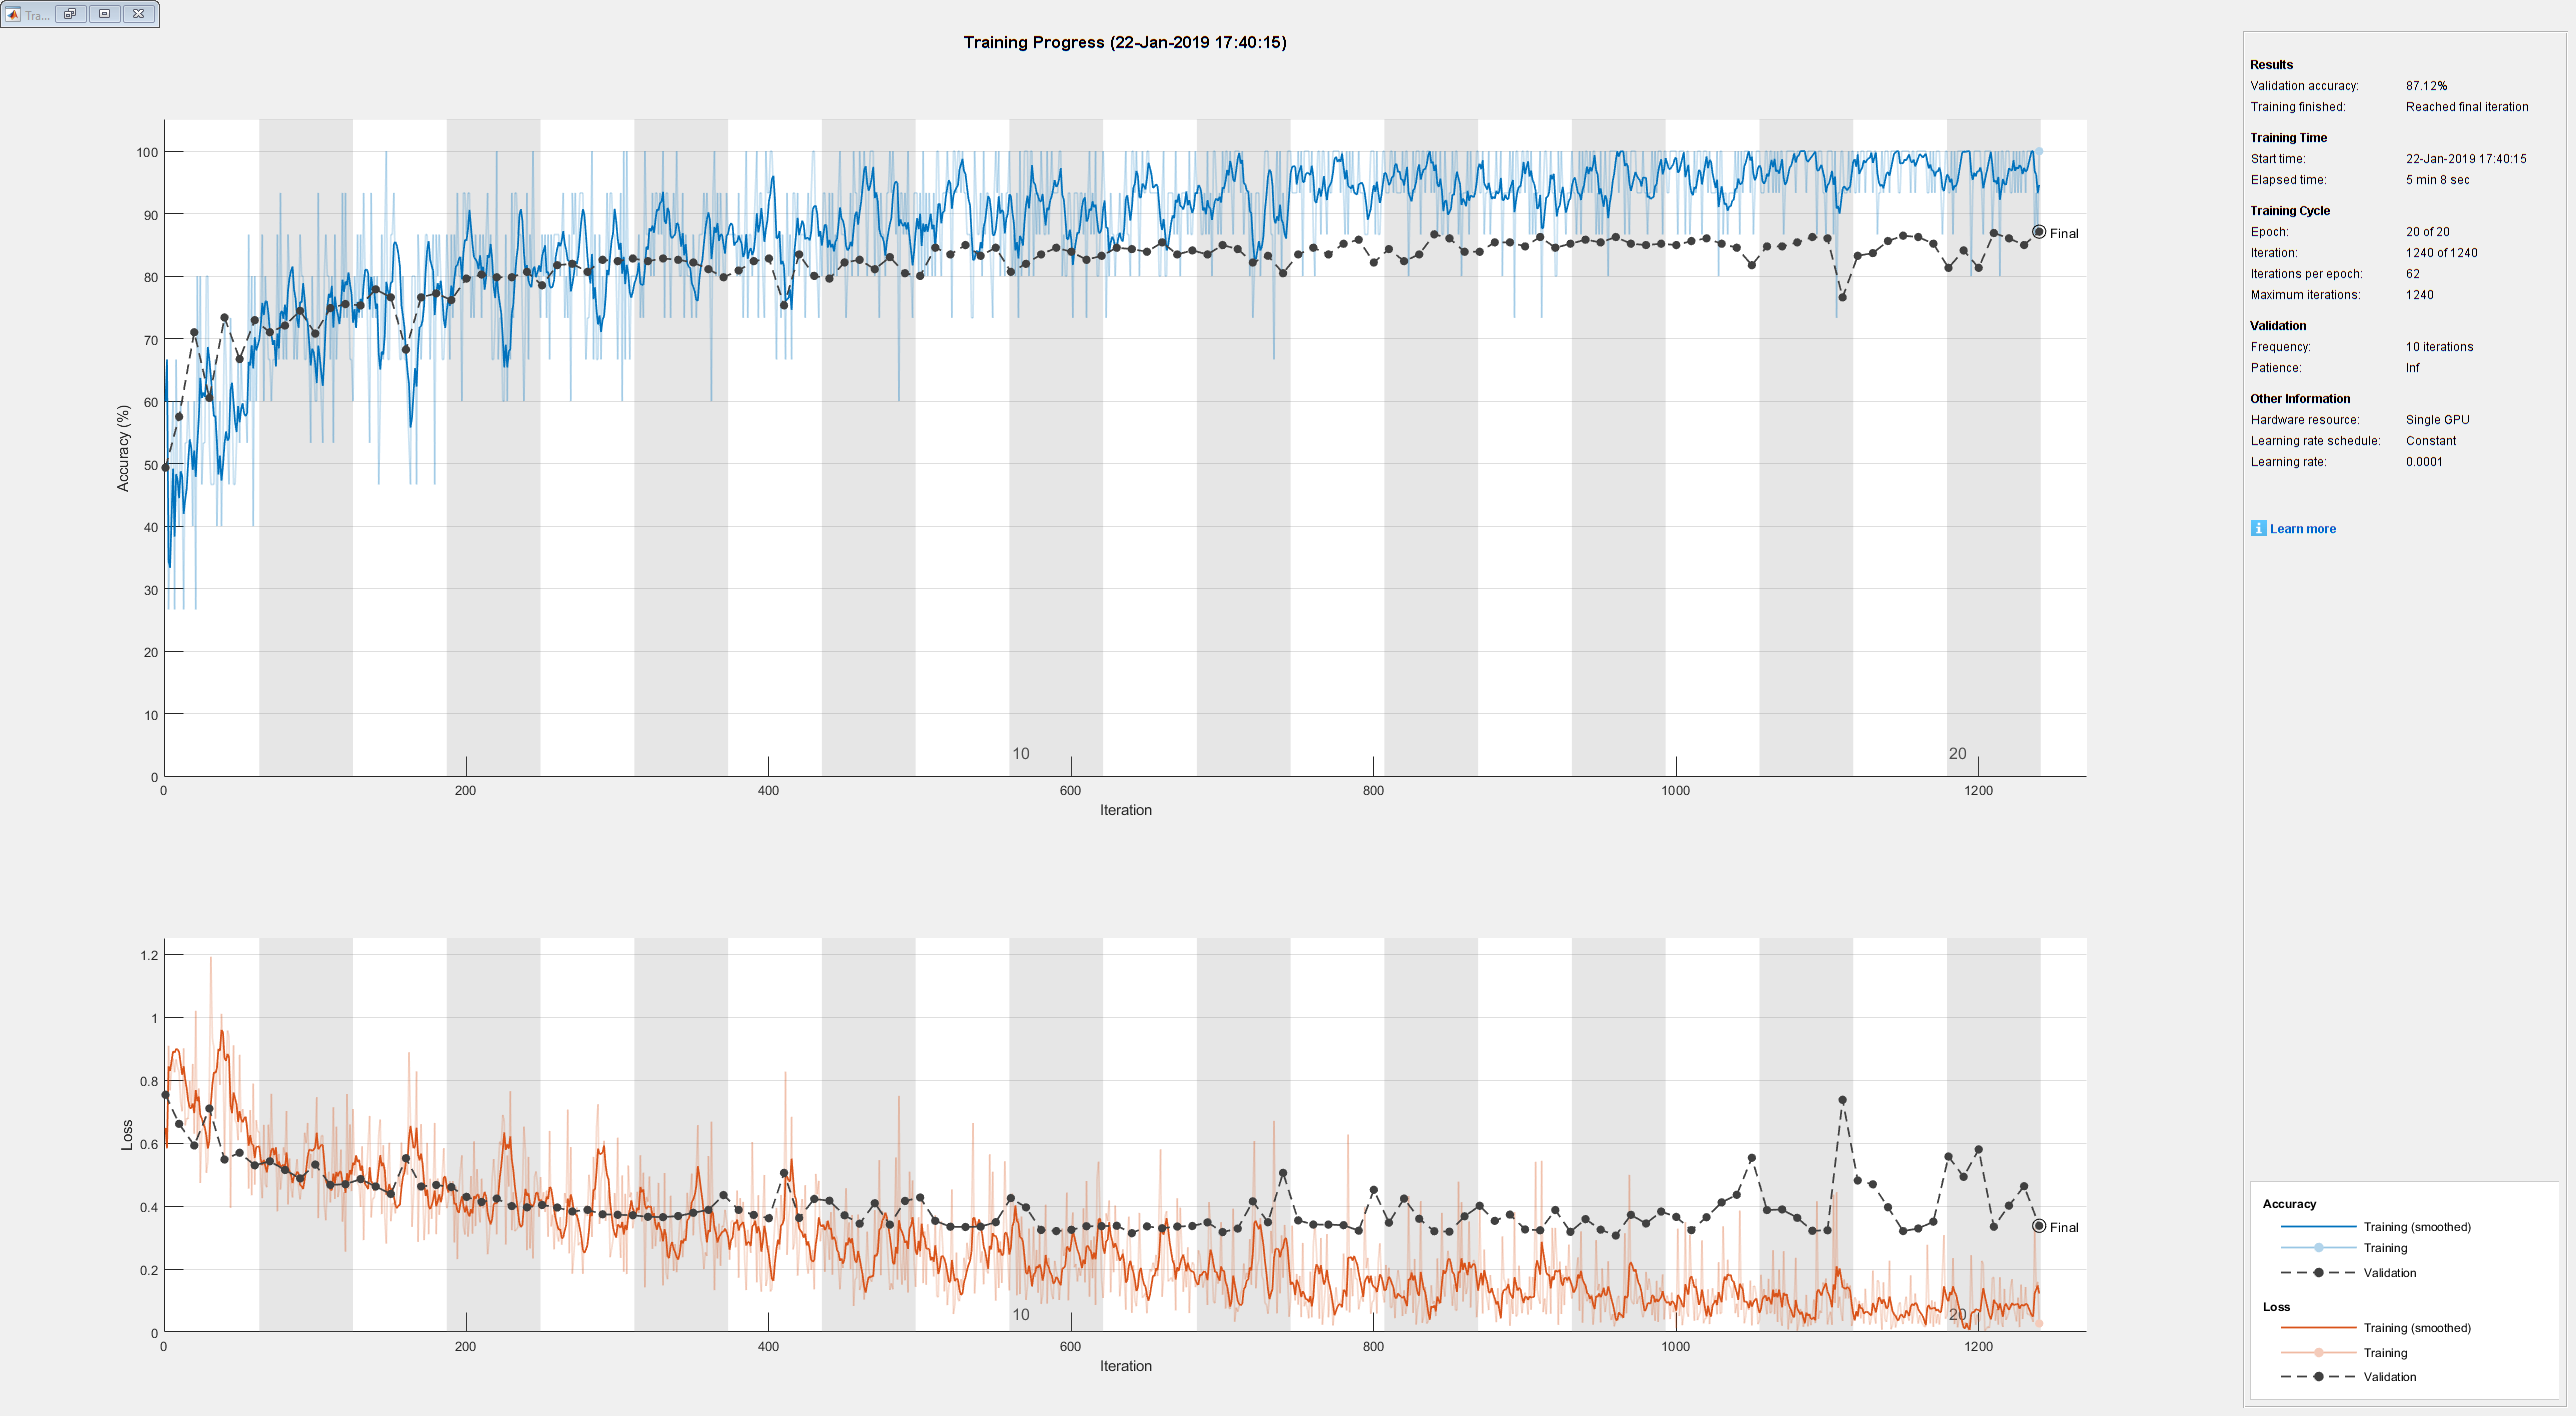

% Train the model
rng(5412)
trainedGN = trainNetwork(imgsTrain,lgraph,options);

The model ends up with 84.5% test accuracy.

% Make predictions on the test set, write out the accuracy and confusion
% matrix
[YPred,probs] = classify(trainedGN,imgsTest);
accuracy = mean(YPred==imgsTest.Labels);
predicted = YPred == "Contamination";
actual = imgsTest.Labels == "Contamination";
display(['Model Accuracy: ',num2str(accuracy)]);

Model Accuracy: 0.88793


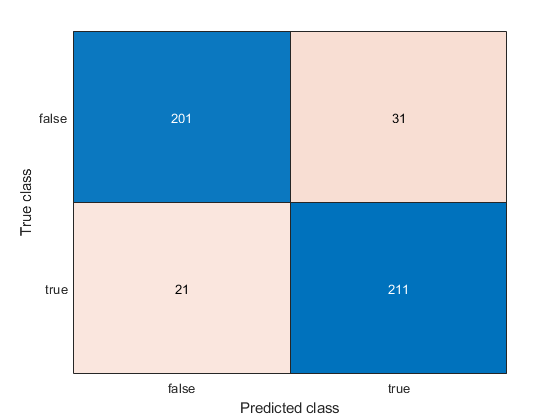


% Create confusion matrix chart
confMat = confusionmat(logical(actual),logical(predicted));
accuracyFrac = sum(diag(confMat))/sum(confMat(:));
cm = confusionchart(logical(actual),logical(predicted));